# Comparison with Current Protocols

format shortG
rawfoldincs = readmatrix("rawfoldincs.txt");
rawfoldincs(:,15:end)=[]

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377
       6.1224       4.6158       4.2724       6.3406        5.555        5.555       6.1277       6.0724        4.147       5.0623       4.6189       3.9479       4.8302       4.2567
       5.4756       4.7525        3.882        3.027          4.5          4.5       3.2186       3.4439       4.1462       6.0479       4.0482       5.3647       6.5694       3.4422
          NaN       2.3012       1.6283       1.3062       2.5181       2.5181       3.6119       2.2886       3.4762       4.1757       2.3177       2.2001       2.0197       2.5865
          NaN          NaN       1.3772       1.2429          NaN      

conforplot =           0.1            0
          0.1            0
       0.1078            3
       0.1078            3
         0.66            5
          0.5            5
       2.7378            7
          0.5            7
          NaN            9
          NaN            9


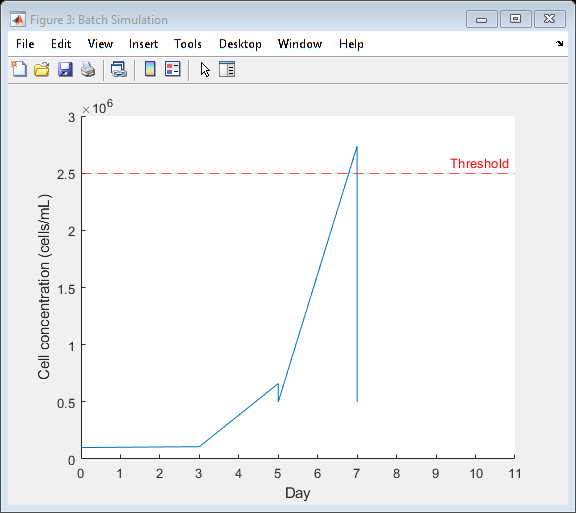

conforplot =           0.1            0
          0.1            0
        0.153            3
        0.153            3
      0.70622            5
          0.5            5
       2.3762            7
          0.5            7
       1.1506            9
          0.5            9


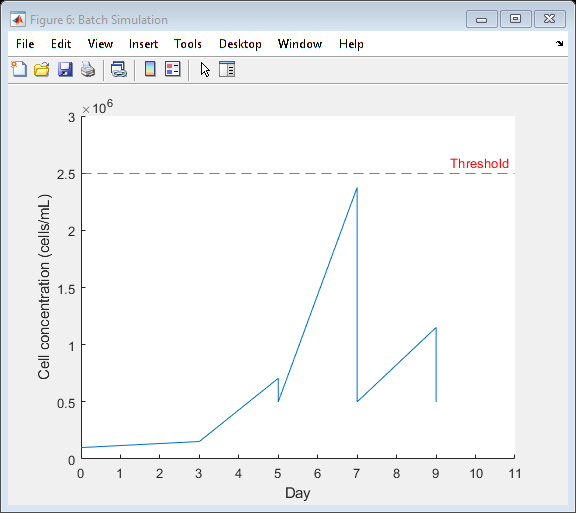

conforplot =           0.1            0
          0.1            0
       0.1358            3
       0.1358            3
      0.58019            5
          0.5            5
        1.941            7
          0.5            7
      0.81417            9
          0.5            9


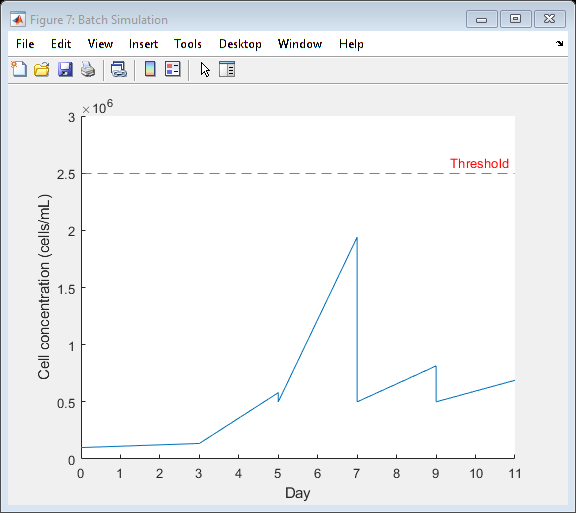

conforplot =           0.1            0
          0.1            0
       0.1548            3
       0.1548            3
      0.98152            5
          0.5            5
       1.5135            7
          0.5            7
      0.65308            9
          0.5            9


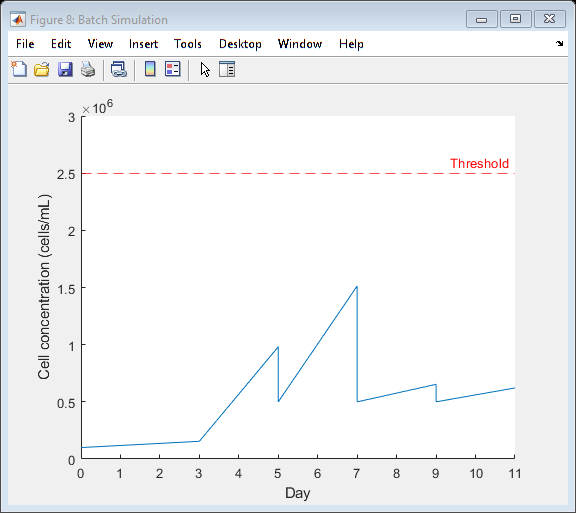

conforplot =           0.1            0
          0.1            0
       0.1052            3
       0.1052            3
      0.58439            5
          0.5            5
         2.25            7
          0.5            7
        1.259            9
          0.5            9


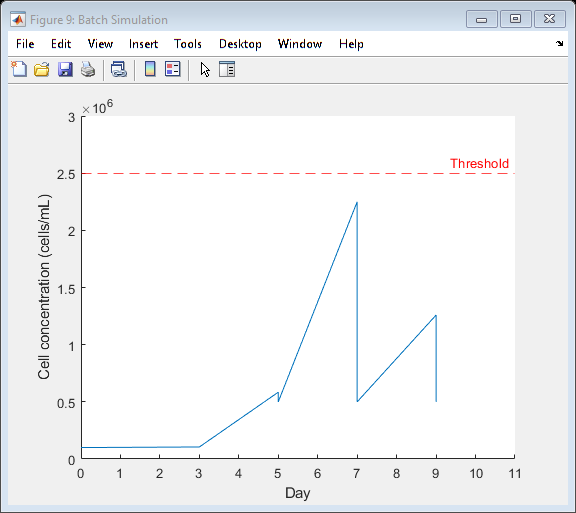

conforplot =           0.1            0
          0.1            0
       0.1052            3
       0.1052            3
      0.58439            5
          0.5            5
         2.25            7
          0.5            7
        1.259            9
          0.5            9


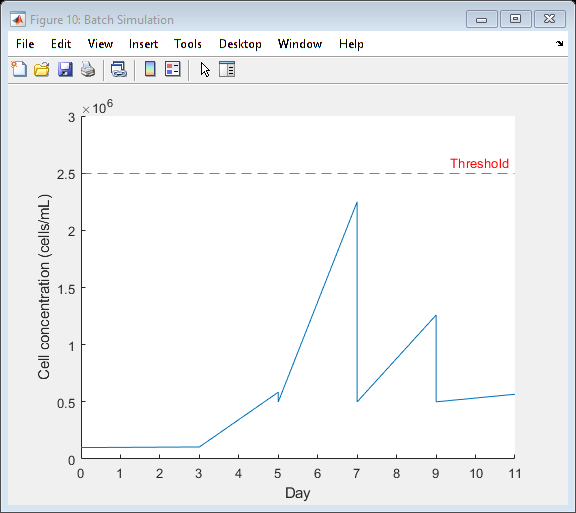

conforplot =           0.1            0
          0.1            0
        0.094            3
        0.094            3
        0.576            5
          0.5            5
       1.6093            7
          0.5            7
        1.806            9
          0.5            9


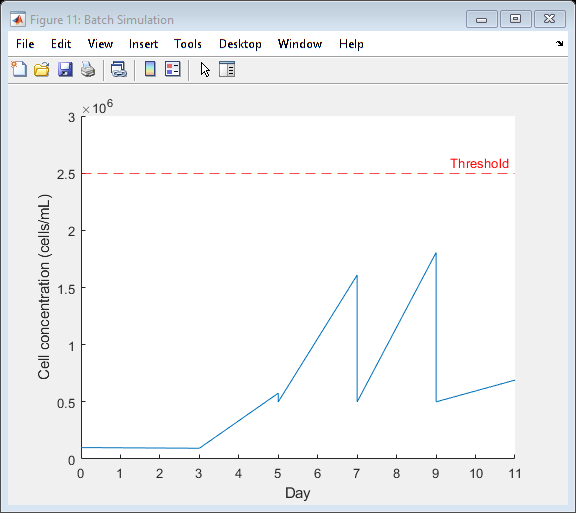

conforplot =           0.1            0
          0.1            0
       0.0718            3
       0.0718            3
        0.436            5
        0.436            5
       1.5015            7
          0.5            7
       1.1443            9
          0.5            9


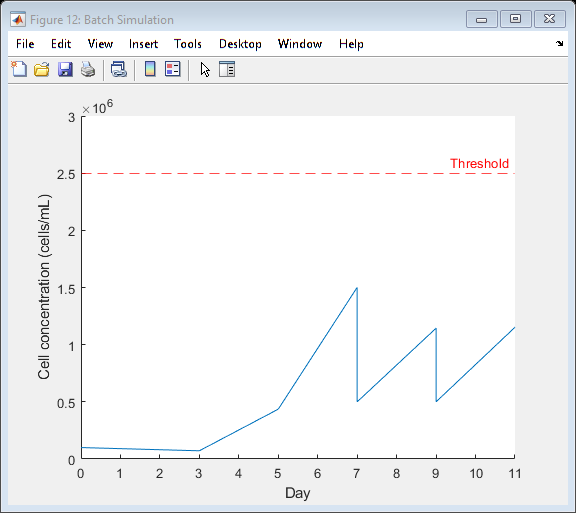

conforplot =           0.1            0
          0.1            0
      0.10855            3
      0.10855            3
      0.45014            5
      0.45014            5
       1.8664            7
          0.5            7
       1.7381            9
          0.5            9


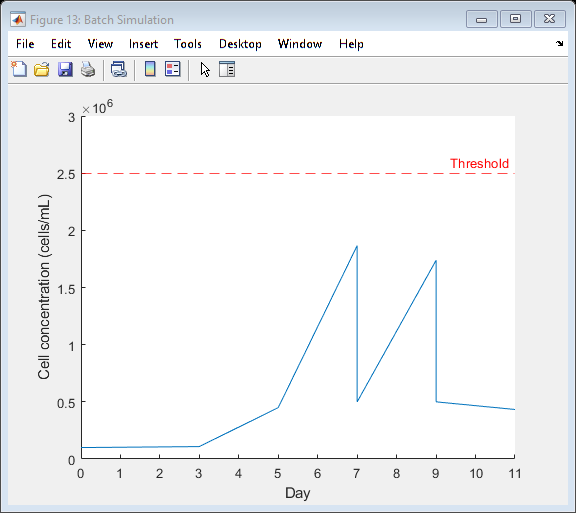

conforplot =           0.1            0
          0.1            0
        0.119            3
        0.119            3
      0.60241            5
          0.5            5
        3.024            7
          0.5            7
       2.0879            9
          0.5            9


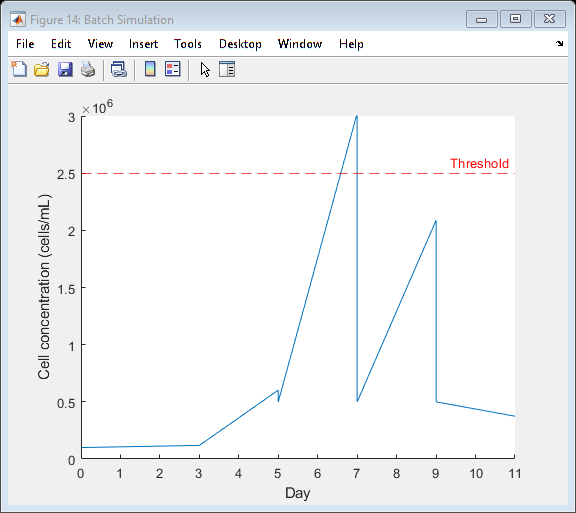

conforplot =           0.1            0
          0.1            0
       0.1131            3
       0.1131            3
      0.52239            5
          0.5            5
       2.0241            7
          0.5            7
       1.1589            9
          0.5            9


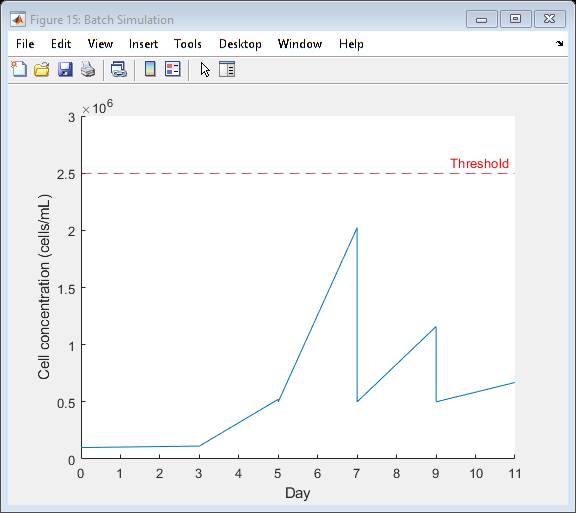

conforplot =           0.1            0
          0.1            0
      0.15582            3
      0.15582            3
      0.61515            5
          0.5            5
       2.6823            7
          0.5            7
          1.1            9
          0.5            9


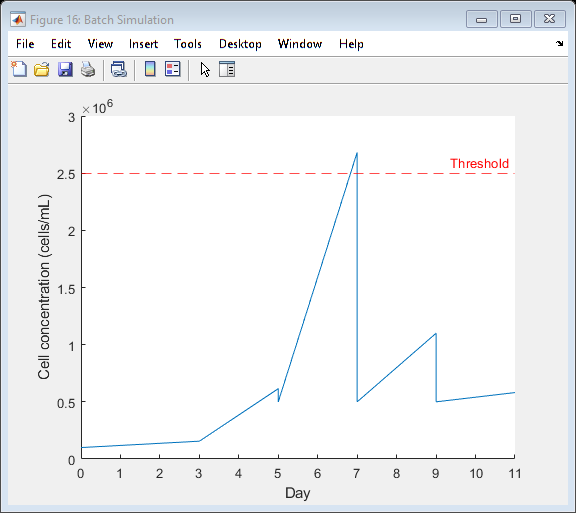

conforplot =           0.1            0
          0.1            0
       0.1952            3
       0.1952            3
      0.94286            5
          0.5            5
       3.2847            7
          0.5            7
       1.0098            9
          0.5            9


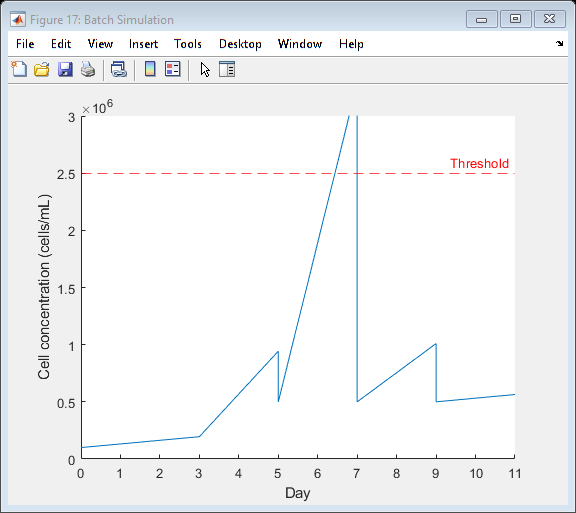

conforplot =           0.1            0
          0.1            0
      0.11377            3
      0.11377            3
      0.48429            5
      0.48429            5
        1.667            7
          0.5            7
       1.2933            9
          0.5            9


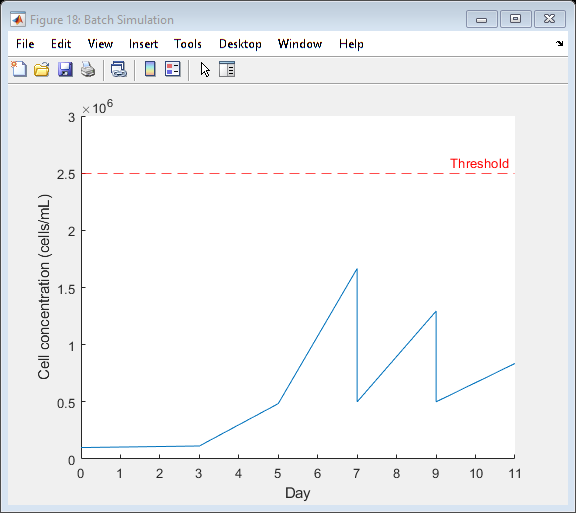

dilutecon = 0.5;
initstate = [0.1,1];
actions = [0.18, 0.21, 0.24, 0.27, 0.3, 1];
day = [0,3,5,7,9,11];
culturenum = 14;
concentrationThreshold = 2.5;
rewards = zeros(numel(culturenum));
simresults = zeros(size(rawfoldincs,1),culturenum);
Reward1=1;
Penalty1=-2.5;

for i=1:culturenum
    State=initstate;
    timeStep=0;
    timsStepStart=0;
    Reward=0;
    foldExMap = rawfoldincs(:,i);
    simresult = zeros(size(rawfoldincs,1),1);
    conforplot = [];
    for j=1:numel(day)
        if day(j)==0 | day(j)==11 | day(j)==3
            Action=0;
        else
            Action=1;
        end
        if j==6
            conforplot = [conforplot; State]; 
        else
            [State,reward,conforplot]=step(State,Action,concentrationThreshold,foldExMap,dilutecon,Reward1,Penalty1,conforplot);
        end

        simresult(j) = State(1);
        if isfinite(reward)
            Reward = Reward + reward;
        end
    end
    
    for k=1:size(conforplot,1)
        conforplot(k,2)=day(conforplot(k,2));
    end
    conforplot
    rewards(i)=Reward;
    simresults(:,i) = simresult; 

    Figure = figure('Name','Batch Simulation','Visible','on','HandleVisibility','off');
    ha = gca(Figure);
    ha.XLimMode = 'manual';
    ha.YLimMode = 'manual';
    ha.XLim = [0,11];
    ha.YLim = [0,3000000];
    xlabel(ha,'Day')
    ylabel(ha,'Cell concentration (cells/mL)')
    ha.TitleHorizontalAlignment = 'right';
    clf;
    hold(ha,'on');
    yline(ha,2500000,'r--','Threshold')      
    ConcentrationPlot = plot(ha,conforplot(:,2),conforplot(:,1).*1000000,'LineStyle','-','Color',[0, 0.4470, 0.7410]);
end


rewards

rewards =      -0.18341     -0.61391      -5.1517      -5.4542     -0.80137      -4.6686      -4.5346      -4.5414     0.029349      -1.0384      -4.8435      -5.1963      -7.3627      -4.7706


simresults

simresults =        0.1078        0.153       0.1358       0.1548       0.1052       0.1052        0.094       0.0718      0.10855        0.119       0.1131      0.15582       0.1952      0.11377
         0.66      0.70622      0.58019      0.98152      0.58439      0.58439        0.576        0.436      0.45014      0.60241      0.52239      0.61515      0.94286      0.48429
       2.7378       2.3762        1.941       1.5135         2.25         2.25       1.6093       1.5015       1.8664        3.024       2.0241       2.6823       3.2847        1.667
          NaN       1.1506      0.81417      0.65308        1.259        1.259        1.806       1.1443       1.7381       2.0879       1.1589          1.1       1.0098       1.2933
          NaN          NaN       0.6886      0.62146          NaN      0.56637      0.69008       1.1525      0.43311      0.37405      0.66905      0.58102      0.56406      0.83551
          NaN          NaN       0.6886      0.62146          NaN      0

totalscoreclinical = sum(rewards)

totalscoreclinical =       -49.131


function [State,reward,conforplot] = step(State,Action,concentrationThreshold,foldExMap,dilutecon,Reward1,Penalty1,conforplot)
    
    % Unpack state vector
    state = State;
    con = state(1);
    time = state(2);
    
    conforplot = [conforplot; [con,time]];

    % Apply system dynamics        
    if Action==1 & con>dilutecon
        con = dilutecon;
    end
    
    conforplot = [conforplot; [con,time]];

    % calculate next state values
    time = time + 1;
    con = con * foldExMap(time);
    
    if con>(concentrationThreshold)
        overthreshold = true;
    else 
        overthreshold = false;
    end
    
    % Update system states
    State = [con,time];

    % Get reward    
    if overthreshold == false
        reward = con*Reward1;
    else
        reward = 5*concentrationThreshold-4*con*Reward1;
    end
    
    if Action==1 & con>dilutecon
        reward = reward + Penalty1;
    end           
end